# Simulate Poisson point processes: Testing distribution

## Introduction

We check that when a large number of Poisson processes of rate lambda are simulated over a time range [0,T]:

- The empirical distribution of the number of events  per process follows a Poisson distribution of parameter lambda*T;

-  The empirical distribution of the occurence times follow an exponential of mean 1/lambda.  

The functions used below rely on the MATLAB function fitdist.

## Empirical data

    % Simulation parameters
    rate = 3;                 
    maxTime = 8;         
    timeStep = 0.01;     
    nbProcesses = 10000;
    % Simulated data
    data = simulatePoissonProcess(rate, maxTime, timeStep, nbProcesses);

## Rate infered from the distribution of the number of events

The infered rate lambda is 3.0137


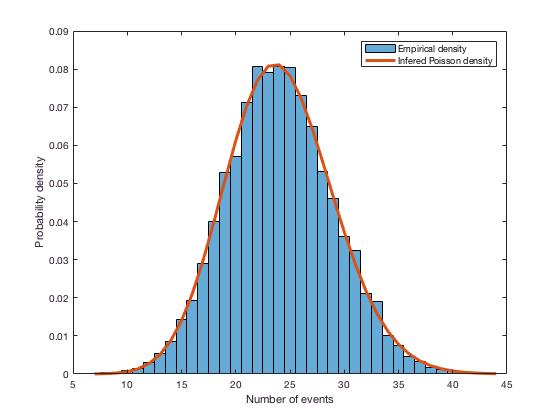

    inferPoissonProcessFromNbEvents( data.nbEvents, maxTime);

## Rate infered from the distribution of the occurrence intervals

The infered rate lambda is 3.0026


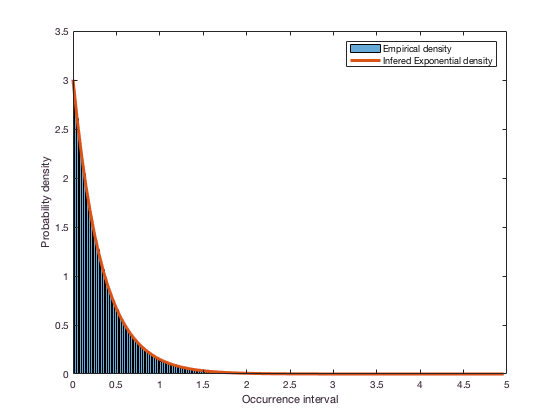

inferPoissonProcessFromOccurrenceIntervals( data.occurrenceIntervals);